clear, clc, close all

res = 500; % resolusion
train_sample = 100; % number of random train samples
test_sample = 50; % number of random test samples
max_require_error = 0.1; 

U = [0,10];
time = linspace(U(1),U(2),res);
g = @(time) -pi/6*sin(time+3*pi/2)-pi/6;
output = g(time);
V = linspace(min(output), max(output), res);

## a

rnd = time(randperm(res));
xtr = rnd(1:train_sample);
xte = rnd(train_sample+1:train_sample+1+test_sample);
ytr = g(xtr);
yte = g(xte);

## a - plot

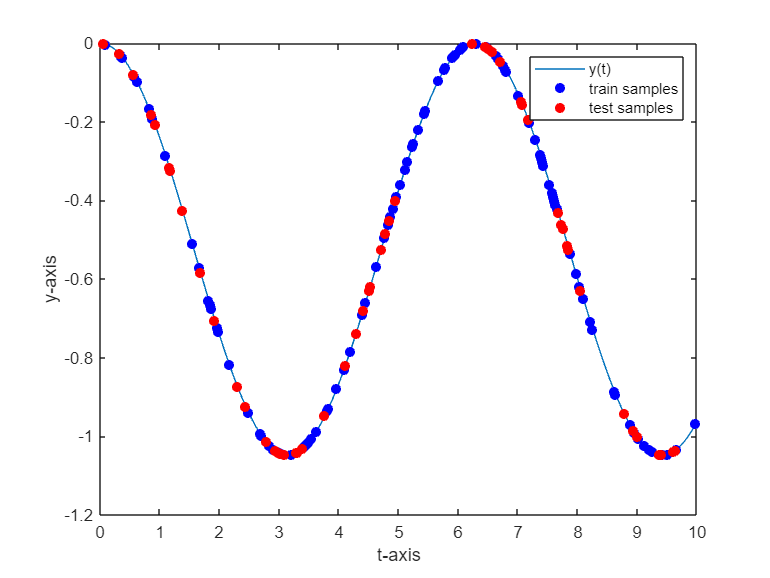

plot(time,g(time))
hold on
scatter(xtr,ytr,'filled','b')
scatter(xte,yte,'filled','r')
xlabel('t-axis'), ylabel('y-axis'), legend('y(t)','train samples', 'test samples')
hold off

## Number of MFs

% max_require_error = 0.1; 
syms tt h e
D1 = diff(g(tt),tt)

$$D1 = -\frac{\pi \,\cos\left(\mathrm{tt}+\frac{3\,\pi }{2}\right)}{6}$$

D2 = diff(g(tt),tt,2)

$$D2 = \frac{\pi \,\sin\left(\mathrm{tt}+\frac{3\,\pi }{2}\right)}{6}$$

infnorm1 = norm(subs(D1,time),'inf')

$$infnorm1 = \frac{\pi \,\cos\left(\frac{3\,\pi }{2}+\frac{3920}{499}\right)}{6}$$

infnorm2 = norm(subs(D2,time),'inf')

$$infnorm2 = \frac{\pi }{6}$$

h1 = double(solve(subs(infnorm1 * h == e, e, max_require_error)))

h1 = 0.1910

h2 = double(solve(subs(1/8 * infnorm2 * h^2 == e, e, max_require_error)));
h2 = h2(h2>0)

h2 = 1.2361

n_mf1 = round(abs(U(2)-U(1))/h1 + 1)

n_mf1 = 53

n_mf2 = round(abs(U(2)-U(1))/h2 + 1)

n_mf2 = 9

test_input = time;
test_output = g(test_input);
n_mf = n_mf2;
tbars = linspace(time(1), time(end), n_mf);
ybars = linspace(min(output), max(output), n_mf);
 

% MFs according to train data - complete - consistent
% triangular a=x(i-1), b=x(i), c=x(i+1)
% tbars = sort(xtr);
% n_mf = numel(xtr);
% ybars = sort(ytr);

Create MF

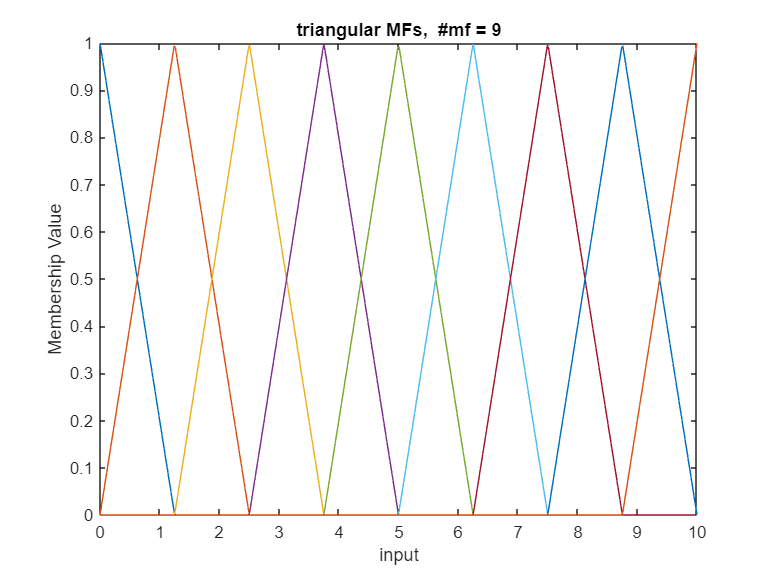

A1 = create_mfx(n_mf,U,tbars,time);

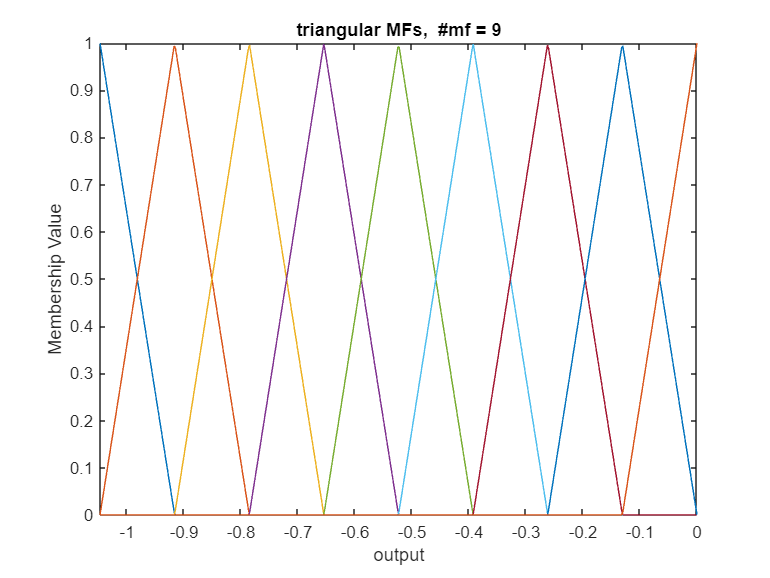

B = create_mfy(n_mf,V,ybars);

METHOD 1 : chapter 10,11

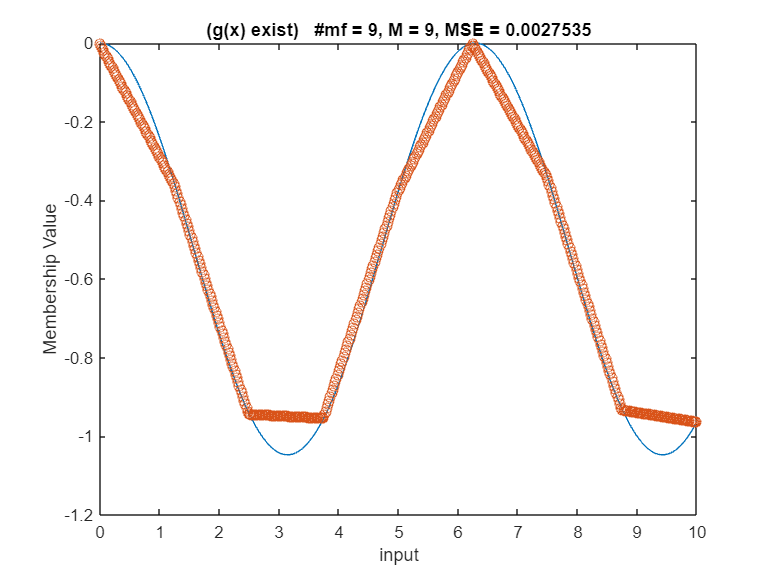

ch1011(g,U,time,n_mf,tbars,test_input,test_output)

METHOD 2: chapter 12

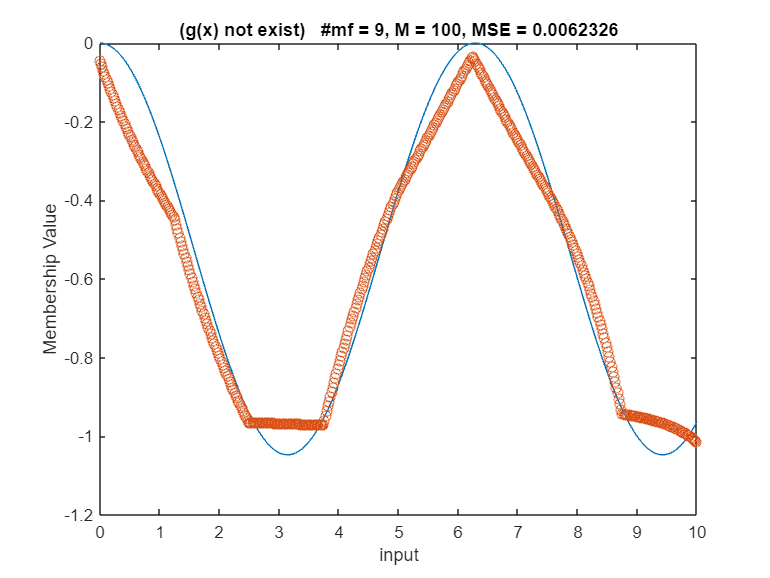

% use n_mf1
ch12(train_sample,A1,B,test_input,test_output,n_mf,g,time,xtr,ytr,ybars)

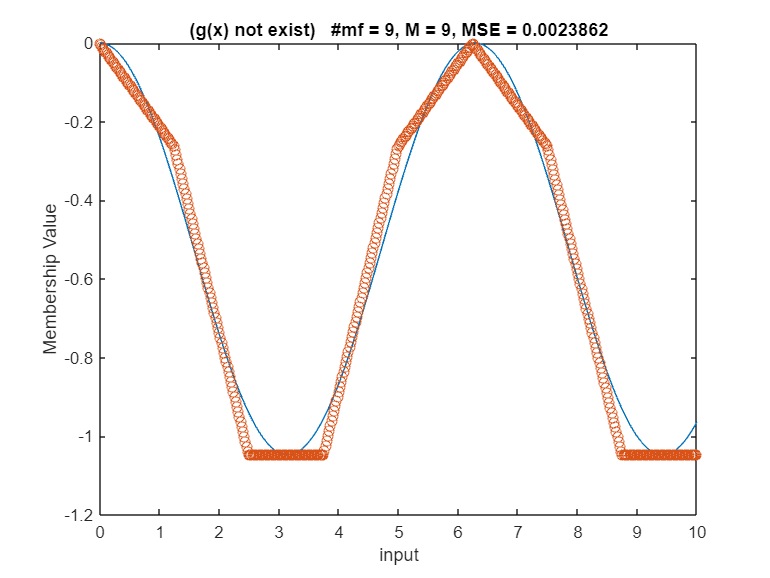


ch12_fixRules(train_sample,A1,B,test_input,test_output,n_mf,g,time,xtr,ytr,ybars)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function ch1011(g,U,time,n_mf,tbars,test_input,test_output)
%% Method 1
% Wang: Chapter(10,11) - normal - complete - consistent - psudoTrapMF

% Step 1: find xbars
xbars = tbars;
% Step 2: ybar
ybars_exact = g(xbars);
% Step 3: fuzzy system
% product - infrence engine
% singletin - fuzzifier
% center average - defuzzifier
mfs_x1 = get_mf(U,n_mf,xbars);
yest_exact = sum(ybars_exact .* mfs_x1.triangular(test_input),2)./sum(mfs_x1.triangular(test_input),2);
% plot
ybar = g(tbars);
stem(ybar,ones(1,n_mf))
xlim([-1.2,0.1]), ylim([0,1.1]), xlabel('output'), ylabel('Membership Value'), title('singleton MFs'), hold off
% plot
mse = sum((yest_exact'-test_output).^2)/numel(test_input);
plot(time,g(time))
hold on
scatter(test_input,yest_exact)
title("(g(x) exist)   #mf = "+n_mf+", M = "+n_mf+", MSE = " + mse)
xlabel('input'), ylabel('Membership Value')
hold off
end

function ch12(train_sample,A1,B,test_input,test_output,n_mf,g,time,xtr,ytr,ybars)
% find rules
[rule, ~] = findRules(train_sample,A1,B,xtr,ytr,n_mf);
% create mega MFs matrix
MFs = RuleMf(rule,{A1,B});
% Fuzzy System with COA
yest = FS.COAdefuzz(test_input, MFs, ybars(rule(:,2)));
% plot
mse = sum((yest-test_output).^2)/numel(test_input);
plot(time,g(time))
hold on
scatter(test_input,yest)
title("(g(x) not exist)   #mf = "+n_mf+", M = "+size(rule,1)+", MSE = " + mse)
xlabel('input'), ylabel('Membership Value')
hold off
end

function ch12_fixRules(train_sample,A1,B,test_input,test_output,n_mf,g,time,xtr,ytr,ybars)
% find rules
[rule, star] = findRules(train_sample,A1,B,xtr,ytr,n_mf);
% find useful rules
new_rules = useful_Rules(rule,star);
% create mega MFs matrix
new_MFs = RuleMf(new_rules,{A1,B});
% Fuzzy System with COA
new_yest = FS.COAdefuzz(test_input, new_MFs, ybars(new_rules(:,2)));
% plot
mse = sum((new_yest-test_output).^2)/numel(test_input);
plot(time,g(time))
hold on
scatter(test_input,new_yest)
title("(g(x) not exist)   #mf = "+n_mf+", M = "+size(new_rules,1)+", MSE = " + mse)
xlabel('input'), ylabel('Membership Value')
hold off
end

function [rule, star] = findRules(train_sample,A1,B,xtr,ytr,n_mf)
% Step 1 : find must active MF for each train data (A* and B*)
% Step 2 : create rules
M = train_sample;
for l = 1:M
    for i = 1:n_mf
        memberX(i) = A1(i).membership(xtr(l));
        memberY(i) = B(i).membership(ytr(l));
    end
    % Step 1
    [starXvalue(l),starX] = max(memberX);
    [starYvalue(l),starY] = max(memberY);
    % Step 2
    rule(l,:) = [starX, starY];    % IF x is A(starX) THEN y is B(starY)
end
star = [starXvalue;starYvalue]';
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function A1 = create_mfx(n_mf,U,tbars,time)
% MF - equal width - complete - consistent - triangular - systematic
A1(1:n_mf) = MF('tri'); % MF objects
for i = 1:n_mf
    if i == 1
        a = U(1);
        b = tbars(1);
        c = tbars(2);
    elseif i == n_mf
        a = tbars(end-1);
        b = tbars(end);
        c = U(end);
    else
        a = tbars(i-1);
        b = tbars(i);
        c = tbars(i+1);
    end
    A1(i).par = {a,b,c};
    A1_mtx(i,:) = A1(i).membership(time);
end

plot(time,A1_mtx)
title("triangular MFs,  #mf = "+n_mf), xlabel('input'), ylabel('Membership Value')
hold off
end

function B = create_mfy(n_mf,V,ybars)
% MF(output) - equal width - complete - consistent - triangular
B(1:n_mf) = MF('tri'); % MF objects
for i = 1:n_mf
    if i == 1
        a = V(1);
        b = ybars(1);
        c = ybars(2);
    elseif i == n_mf
        a = ybars(end-1);
        b = ybars(end);
        c = V(end);
    else
        a = ybars(i-1);
        b = ybars(i);
        c = ybars(i+1);
    end
    B(i).par = {a,b,c};
    B_mtx(i,:) = B(i).membership(V);
end

plot(V,B_mtx)
title("triangular MFs,  #mf = "+n_mf), xlabel('output'), ylabel('Membership Value'), xlim([V(1),V(end)])
hold off
end